# Problem 2

defining parameters

n = 500; %n # random points.
L = 20;
rmin = .7; r1=70; rmax = rmin*r1; %parameters
xyz = rand(3,1)*L;
 
x = [xyz(1) zeros(1,n-1)];  y = [xyz(2) zeros(1,n-1)]; z = [xyz(2) zeros(1,n-1)]%initialize the random points

z =     0.1006         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


xx=x; yy=y;
k = 1;

## a:

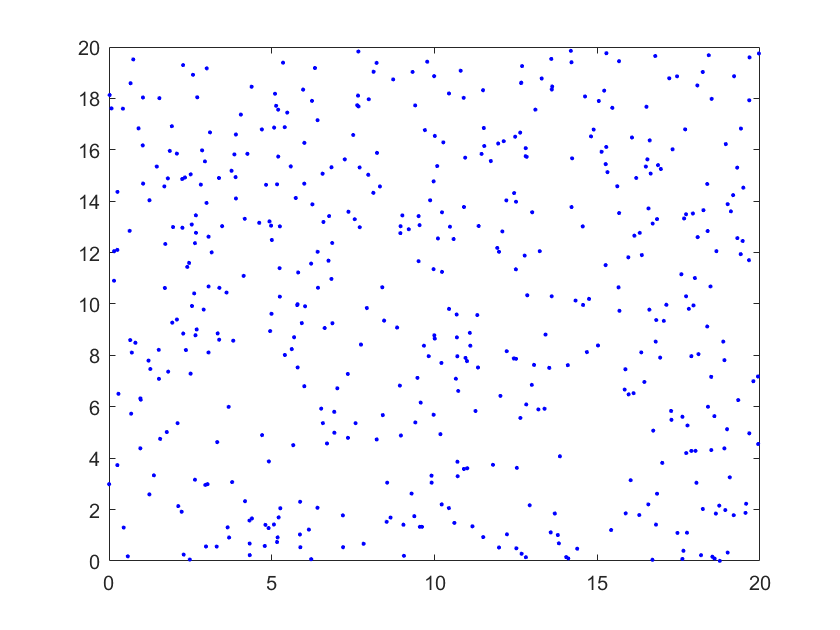

for i =2: n
    xya = rand(2,1)*L;
    xa = xya(1);
    ya = xya(2);
    xx(i) = xa;
    yy(i) = ya;
end
plot(xx,yy,'b.')

## b:

tic
while k < n
    cen = rand(2,1)*L; %starting point(centers)
    cx = cen(1);        % x component
    cy = cen(2);        % y component
    for j = 1:n
        rm = rmax;
        rmax = sqrt((x(j)-cx)^2+(y(j)-cy)^2);
        rmax = min(rm,rmax);
    end
    if rmax > rmin
        k = k+1;
        x(k) = cx;
        y(k) = cy;
    end
    rmax = rmin*r1;
end
toc

Elapsed time is 0.079859 seconds.


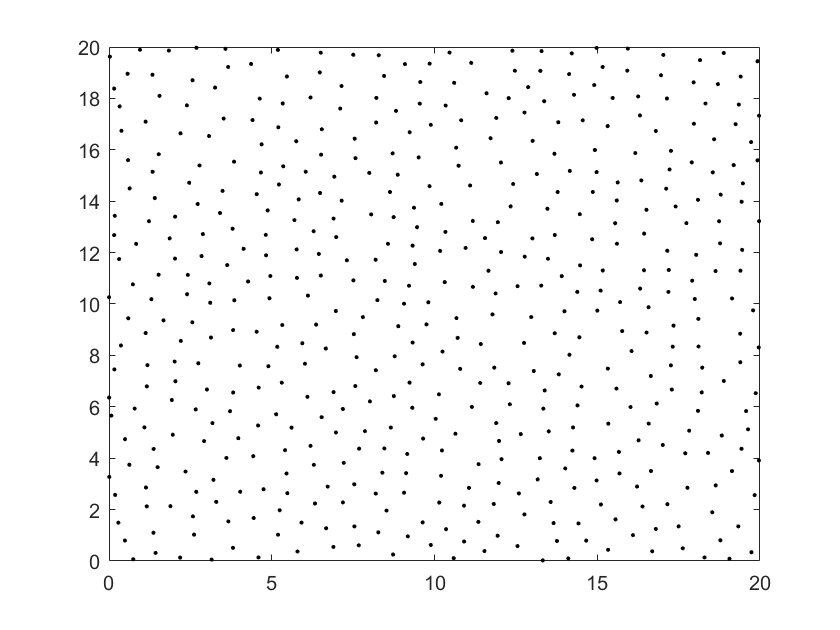

plot(x,y,'k.')

## c:

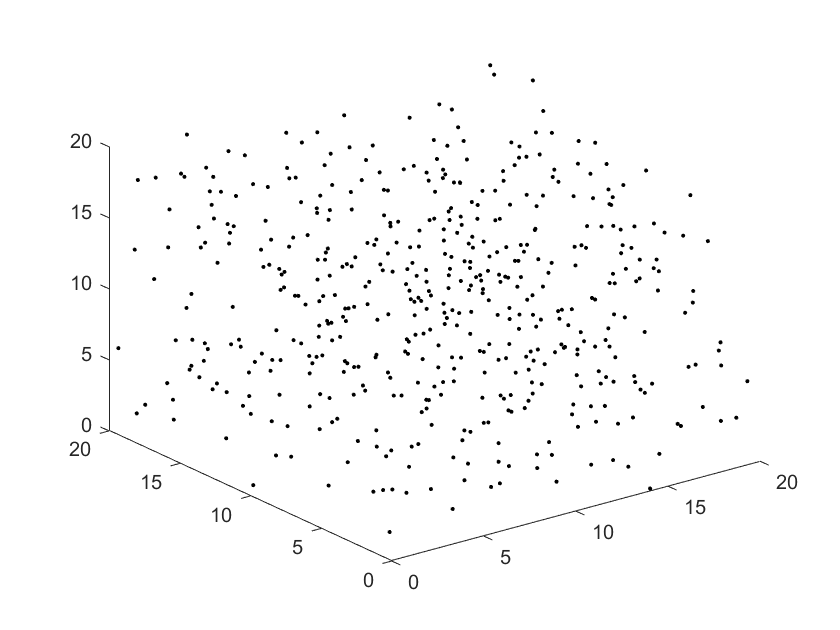

rmin = 1; 
r = rmin*100;
k = 1;
while k < n
    cen = rand(3,1)*L;
    cx = cen(1);
    cy = cen(2);
    cz = cen(3);
    for j = 2:n
        rm = rmax;
        rmax = sqrt((x(j)-cx)^2+(y(j)-cy)^2+(z(j)-cz)^2);
        rmax = min(rm,rmax);
    end
    if rmax > rmin
        k = k+1;
        x(k) = cx;
        y(k) = cy;
        z(k) = cz;
    end
    rmax = rmin*r1;
end

plot3(x,y,z,'k.')